load('proj8Data.mat');

load('roiMasks.mat')

time_v = cumsum(dTime_v);   % Time at the completion of each image.

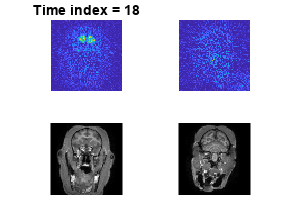

nTimes = length(time_v);
% Display PET (and MRI) images at each time point:
figure
bgImageMax = max(bgPetImage_3d(:));
% Make 3D arrays of identical pages to display MR images in grayscale:
bgMrColor_3d = cat(3, bgMrImage_m, bgMrImage_m, ...
    bgMrImage_m)/max(bgMrImage_m(:));
cbMrColor_3d = cat(3, cbMrImage_m, cbMrImage_m, ...
    cbMrImage_m)/max(cbMrImage_m(:));
for timeIndex = 1:nTimes
    % Show PET image of basal ganglia:
    subplot(2, 2, 1)
    bgPetImage_m = squeeze(bgPetImage_3d(:, :, timeIndex));
    imagesc(bgPetImage_m)
    set(gca, 'CLim', [0, bgImageMax])
    axis image; axis off 
    title(['Time index = ', num2str(timeIndex)])
    % Show PET image of cerebellum:
    subplot(2, 2, 2)
    cbPetImage_m = squeeze(cbPetImage_3d(:, :, timeIndex));
    imagesc(cbPetImage_m)
    set(gca, 'CLim', [0, bgImageMax])
    axis image; axis off   
    % Show MR image of basal ganglia:
    subplot(2, 2, 3)
    image(bgMrColor_3d)
    axis image; axis off
    % Show MR image of cerebellum:
    subplot(2, 2, 4)
    image(cbMrColor_3d)
    axis image; axis off
    pause(1)
end

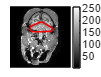

figure
image(cbMrImage_m),axis image; axis off; colormap(gray); colorbar

% title('Define region of interest...')
% [cbRoiMask_m, x_v, y_v] = roipoly;
line(x_v, y_v, 'LineWidth', 1, 'Color', 'r')

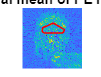

[nRows, nCols, nTimes] = size(cbPetImage_3d);
cbPetMean = zeros(nRows,nCols);
for row = 1:nRows
    for col = 1:nCols
        cbPetMean(row,col) = mean(cbPetImage_3d(row,col,:));
    end
end
figure
imagesc(cbPetMean),axis image; axis off
title('Temporal mean of PET images')
line(x_v, y_v, 'LineWidth', 1, 'Color', 'r')

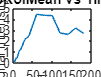

cbRoiMean_v = zeros(1,nTimes);
numel = sum(sum(cbRoiMask_m));
for timeIndex = 1: nTimes
    sumRoiIntensity = sum(sum(cbRoiMask_m.*cbPetImage_3d(:,:,timeIndex)));
    cbRoiMean_v(timeIndex) = sumRoiIntensity/numel;
end
figure
plot(time_v, cbRoiMean_v)
title('cbRoiMean vs Time')
xlabel('Time') 
ylabel('Mean ROI Signal intensity - Cerebellum')

## Basal ganglia

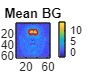

[nRows, nCols, nTimes] = size(bgPetImage_3d);
bgPetMean = zeros(nRows,nCols);
for row = 1:nRows
    for col = 1:nCols
        bgPetMean(row,col) = mean(bgPetImage_3d(row,col,:));
    end
end
figure
imagesc(bgPetMean),axis image; colorbar
% [bgRoiMask_m, xBg_v, yBg_v] = roipoly;
line(xBg_v, yBg_v, 'LineWidth', 1, 'Color', 'r')
title('Mean BG')

% save('roiMasks.mat', ...
%     "cbRoiMask_m","x_v","y_v", ...
%     'bgRoiMask_m','xBg_v','yBg_v');

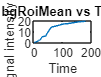

bgRoiMean_v = zeros(1,nTimes);
numel = sum(sum(bgRoiMask_m));
for timeIndex = 1: nTimes
    sumRoiIntensity = sum(sum(bgRoiMask_m.*bgPetImage_3d(:,:,timeIndex)));
    bgRoiMean_v(timeIndex) = sumRoiIntensity/numel;
end
figure
plot(time_v, bgRoiMean_v)
title('bgRoiMean vs Time')
xlabel('Time') 
ylabel('Mean ROI Signal intensity - Basal Ganglia')

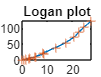

% reference CB over BG
% bgRoiX_v = [];
% for timeIndex = 1:nTimes
%     integratedcbRoiMean = dot(time_v(1:timeIndex),cbRoiMean_v(1:timeIndex));
%     bgRoiX_v(end+1) = integratedcbRoiMean/bgRoiMean_v(timeIndex);
% end
% 
% bgRoiY_v = [];
% for timeIndex = 1:nTimes
%     integratedbgRoiMean = dot(time_v(1:timeIndex),bgRoiMean_v(1:timeIndex));
%     bgRoiY_v(end+1) = integratedbgRoiMean/bgRoiMean_v(timeIndex);
% end

bgRoiX_v = cumtrapz(time_v,cbRoiMean_v)./bgRoiMean_v;
bgRoiY_v = cumtrapz(time_v,bgRoiMean_v)./bgRoiMean_v;
figure
plot(bgRoiX_v, bgRoiY_v, '-', bgRoiX_v, bgRoiY_v, '+')
title('Logan plot')

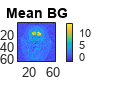

nFitPoints = 4;
% Calculate a mask array for bgPetImage_3d, 
% indicating where the (temporal) mean PET pixel intensity 
% is at least 5% of the maximum in the mean image. 

figure
imagesc(bgPetMean), axis image; colorbar
title('Mean BG')

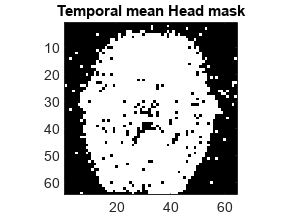


bgImageMax = max(bgPetMean(:));
headMask_m = (bgPetMean > 0.05*bgImageMax);
figure
imagesc(headMask_m), colormap(gray), axis image
title('Temporal mean Head mask')

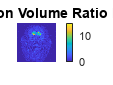


dvr_m = zeros(nRows,nCols);
for row = 1:nRows
    for col = 1: nCols
        if (headMask_m(row, col) == 1)
            bgPetPixel_v = squeeze(bgPetImage_3d(row, col, :))';
            bgPetImage_3dX_v = cumtrapz(time_v,cbRoiMean_v)./ ...
                                                    bgPetPixel_v;
            bgPetImage_3dY_v = cumtrapz(time_v,bgPetPixel_v)./ ...
                                                    bgPetPixel_v;
            % ------- calc slope of Logan plot ----------
            coeff = polyfit( ...
                bgPetImage_3dX_v(end-nFitPoints+1:end), ...
                bgPetImage_3dY_v(end-nFitPoints+1:end), ...
                1);
            if (coeff(1) > 0)
                dvr_m(row, col) = coeff(1);   % DVR = slope.
            else
                dvr_m(row, col) = 0;
            end
        end
    end
end 

%-----------------------------------
% Display DVR map:
figure
imagesc(dvr_m)
colorbar
axis image
axis off
title('Distribution Volume Ratio Map')

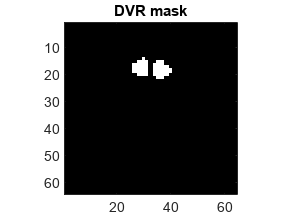

colorMap_m = colormap;
nColors = size(colorMap_m, 1);
 
% % Show thresholded DVR on MRI:
figure
% % Insert your code here to calculate a mask where the DVR values
% % exceed half their maximum value. Name the mask dvrMask_m:

% imageMax = max(bgPetMean);
dvrMax = max(dvr_m(:));
dvrMask_m = (bgPetMean > 0.5*dvrMax);
figure
imagesc(dvrMask_m), colormap(gray), axis image
title('DVR mask')

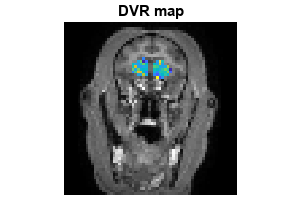



% Render pixels inside dvrMask in color. Use same colormap as above:
colorIndex_v = 1 + round((nColors-1) * dvr_m(:) / max(dvr_m(:)));
redDvr_m = dvrMask_m .* reshape(colorMap_m(colorIndex_v, 1), ...
   size(dvrMask_m));
greenDvr_m = dvrMask_m .* reshape(colorMap_m(colorIndex_v, 2), ...
   size(dvrMask_m));
blueDvr_m = dvrMask_m .* reshape(colorMap_m(colorIndex_v, 3), ...
   size(dvrMask_m));
% Display the rest of the image in gray:
maskedMrImage_m = (1-dvrMask_m) .* bgMrImage_m / ...
    max(bgMrImage_m(:));
color_3d = cat(3, maskedMrImage_m + redDvr_m, ...
    maskedMrImage_m + greenDvr_m, ...
    maskedMrImage_m + blueDvr_m);
image(color_3d)
%h = colorbar;
axis image
axis off
title('DVR map')